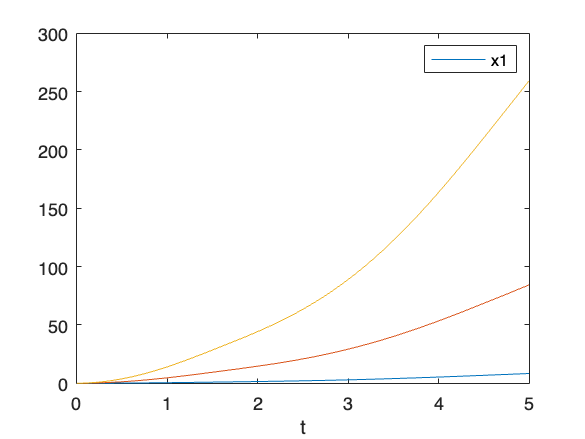

clear, clc
tfin=5;
x0=[0, 0, 10000];
[t, x] = ode45(@(t, x) idk(t, x, 10), [0, tfin], x0);
plot(t, x(:, 1))
hold on
[t, x] = ode45(@(t, x) idk(t, x, 100), [0, tfin], x0);
plot(t, x(:, 1))
hold on
[t, x] = ode45(@(t, x) idk(t, x, 300), [0, tfin], x0);
plot(t, x(:, 1))
xlabel('t')
hold on
legend('x1')

function dxdt = idk(t, x, delta_u)
    k = 1000;
    g = 50;
    G = 6.673e-11;
    M = 5.98e24;
    R = 6.37e6;
    dxdt = [0; 0; 0];
    u=(G*M)/(k*R^2)*exp(-G*M*t/(k*R^2))*10000 + delta_u*abs(cos(t));
    dxdt(1)=x(2);
    dxdt(2)=(k*u-g*x(2))/x(3)-(G*M)/((R+x(1))^2);
    dxdt(3)=-u;
end